## Full System:


$$R_{growth}=  (\psi_g + \psi_d)\cdot\frac{(\eta_AA + 1)^{n_1} + \left(\frac{P_R}{\delta}\right)^{n_1}}{(\eta_B B_{ext} + 1)(\eta_AA+ 1)^{n_1}+ \left( \frac{P_R}{\delta} \right)^{n_1} } - \psi_d-\psi_C \cdot \frac{\eta_{I} I \cdot  \left(\frac{P_C}{\delta}\right)^{n_2}}{\eta_{I}I \cdot \left(\frac{P_C}{\delta}\right)^{n_2}+(\eta_AA +1)^{n_2}} $$



$$\frac{\textrm{dy}}{\textrm{dt}}=R_{\textrm{growth}\;} \cdot y\left(1-y^{\upsilon } \right)$$


Parameter list:

x(1) = $\psi_g$=$\delta$

x(2) = $\psi_C$

x(3) = $P_C \cdot {\left(\eta_I \cdot I\right)}^{\frac{1}{n_2 }}$

x(4) = $\psi_d$

x(5) = $\eta_B B_{\textrm{ext}}$

x(6) = $P_R$

x(7) = $n_1$

x(8) = $n_2$

# Load data

clear all; close all;
addpath('./MatlabFuncs/')

load('Data/Param_Fit2.mat', 'x_both'); %%mac syntax
% load('Data\Param_Fit2.mat', 'x_both');
load('Data/Param_Fit3.mat', 'x_all'); %%mac syntax
% load('Param_Fit3.mat', 'x_all');

xdata = [0, .2, .5, 1, 2, 5, 10, 20, 50, 100];

run('./MatlabFuncs/FuncGenerator.m');

auxins = logspace(-2,2,100);

# Time Trajectories 

## *Varied initial Conditions*

param = x_all %x_both; 

param =     0.0416    0.0590    0.1663    0.0260   16.2997    7.7079    1.5070    0.7421


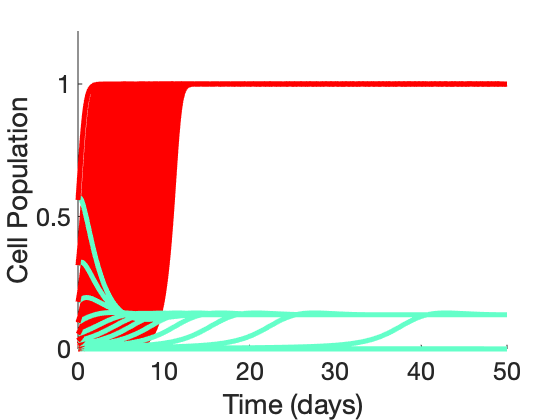


tspan = linspace(0, 50 * 24, 1000);

%Set known values
B_ext = 50; %ug
AP = 20; %uM

c0 = logspace(-5, -0.25, 20);
a0 = 10; %linspace(5,20,5);
[A1, N1] = meshgrid(a0,c0);

figure(1);

cir_on = [];
cir_off = [];

for i = 1 : numel(A1)
    y0 = [A1(i), N1(i)];
    [t,f] = ode45(@(t,y) DynSys(t,y,param,B_ext,AP),tspan,y0');
    [tc,fc] = ode45(@(t,y) DynSys(t,y,param,0,0),tspan,y0');
    
    cir_on = [cir_on, f(:,2)];
    cir_off = [cir_off, fc(:,2)];
    
    hold on;
    plot(tspan./24,f(:,2),'k','Linewidth',5,'Color',[100,255,201]./255)
    plot(tspan./24,fc(:,2),'k','Linewidth',5,'Color',[1,0,0])
end

save("Data\Dynamcs.mat", "cir_on", "cir_off", "tspan");

xlabel('Time (days)')
ylabel('Cell Population')

ax1 = gca;
ax1.FontSize = 25;

## *Paradoxical Feedback Response to Mutation*

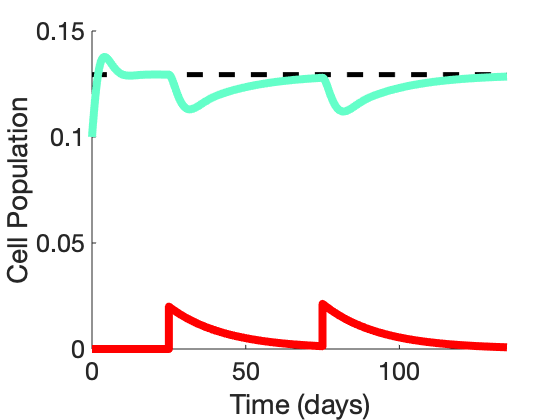

T1 = 25;
tspan1 = linspace(0,T1*24,1000);
y01 = [10, 0.1, 0];

[t1,f1] = ode45(@(t,y) DynSys_mut(t,y,param,B_ext,AP),tspan1,y01');

%1st mutation
T2 = 75;
tspan2 = linspace(T1*24,T2*24,1000);
y02 = f1(end,:) + [0, 0, 0.02];

[t2,f2] = ode45(@(t,y) DynSys_mut(t,y,param,B_ext,AP),tspan2,y02');

%2nd mutation
T3 = 135;
tspan3 = linspace(T2*24,T3*24,1000);
y03 = f2(end,:) + [0, 0, 0.02];

[t3,f3] = ode45(@(t,y) DynSys_mut(t,y,param,B_ext,AP),tspan3,y03');

t_all = [t1; t2; t3];
f_all = [f1; f2; f3];

save("Data\Dynamcs_mut1.mat", 't_all', 'f_all')

figure(2)
clf; hold on;

plot(t_all./24,ones(size(t_all)).*f1(end,2),'--','LineWidth', 4, 'Color', [0,0,0]);
plot(t_all./24, f_all(:,2), 'LineWidth', 8, 'Color', [100,255,201]./255);
plot(t_all./24, f_all(:,3), 'LineWidth', 8, 'Color', [1,0,0]);


xlabel('Time (days)')
ylabel('Cell Population')
xlim([0, T3])
ax2 = gca;
ax2.FontSize = 25;
box off;

## *Simple Feedback Response to Mutation*

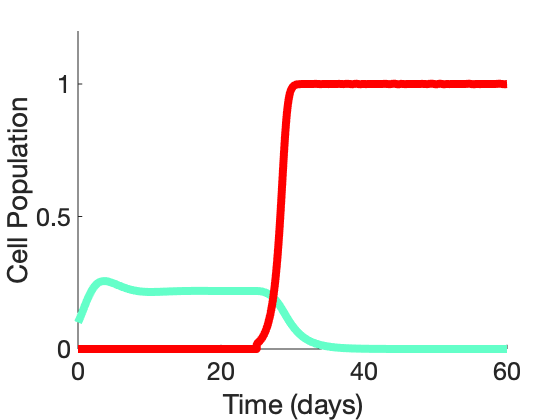

x_both_sf = param;
x_both_sf(2) = 0;
x_both_sf(3) = 0;


tspan1 = linspace(0,T1*24,1000);
y01 = [10, 0.1, 0];

[t1,f1] = ode45(@(t,y) DynSys_mut(t,y,x_both_sf,B_ext,0),tspan1,y01');

%1st mutation
tspan2 = linspace(T1*24,T2*24,1000);
y02 = f1(end,:) + [0, 0, 0.02];

[t2,f2] = ode45(@(t,y) DynSys_mut(t,y,x_both_sf,B_ext,0),tspan2,y02');

%2nd mutation
tspan3 = linspace(T2*24,T3*24,1000);
y03 = f2(end,:) + [0, 0, 0.02];

[t3,f3] = ode45(@(t,y) DynSys_mut(t,y,x_both_sf,B_ext,0),tspan3,y03');

t_all = [t1; t2; t3];
f_all = [f1; f2; f3];

save("Data\Dynamcs_mut2.mat", 't_all', 'f_all')

figure(3)
clf; hold on;

plot(t_all./24, f_all(:,2), 'LineWidth', 8, 'Color', [100,255,201]./255);
plot(t_all./24, f_all(:,3), 'LineWidth', 8, 'Color', [1,0,0]);

xlabel('Time (days)')
ylabel('Cell Population')
xlim([0, 60])
ax3 = gca;
ax3.FontSize = 25;
box off;